# Recurrent neural network

## Architecture

NRlayers = 0;
NFFlayers = 1;
NFFneurons = Ninputs;
Hactivation = 'reluLayer';
Oactivation = 'tanhLayer';
dropout = 0;
Winitializer = 'narrow-normal';
Binitializer = 'narrow-normal';
RWinitializer = 'narrow-normal';
Rnet = RNN(Ninputs, Noutputs, NRlayers, NFFlayers, Nwindow, NFFneurons, Hactivation, Oactivation, dropout, Winitializer, Binitializer, RWinitializer).net;

## Training

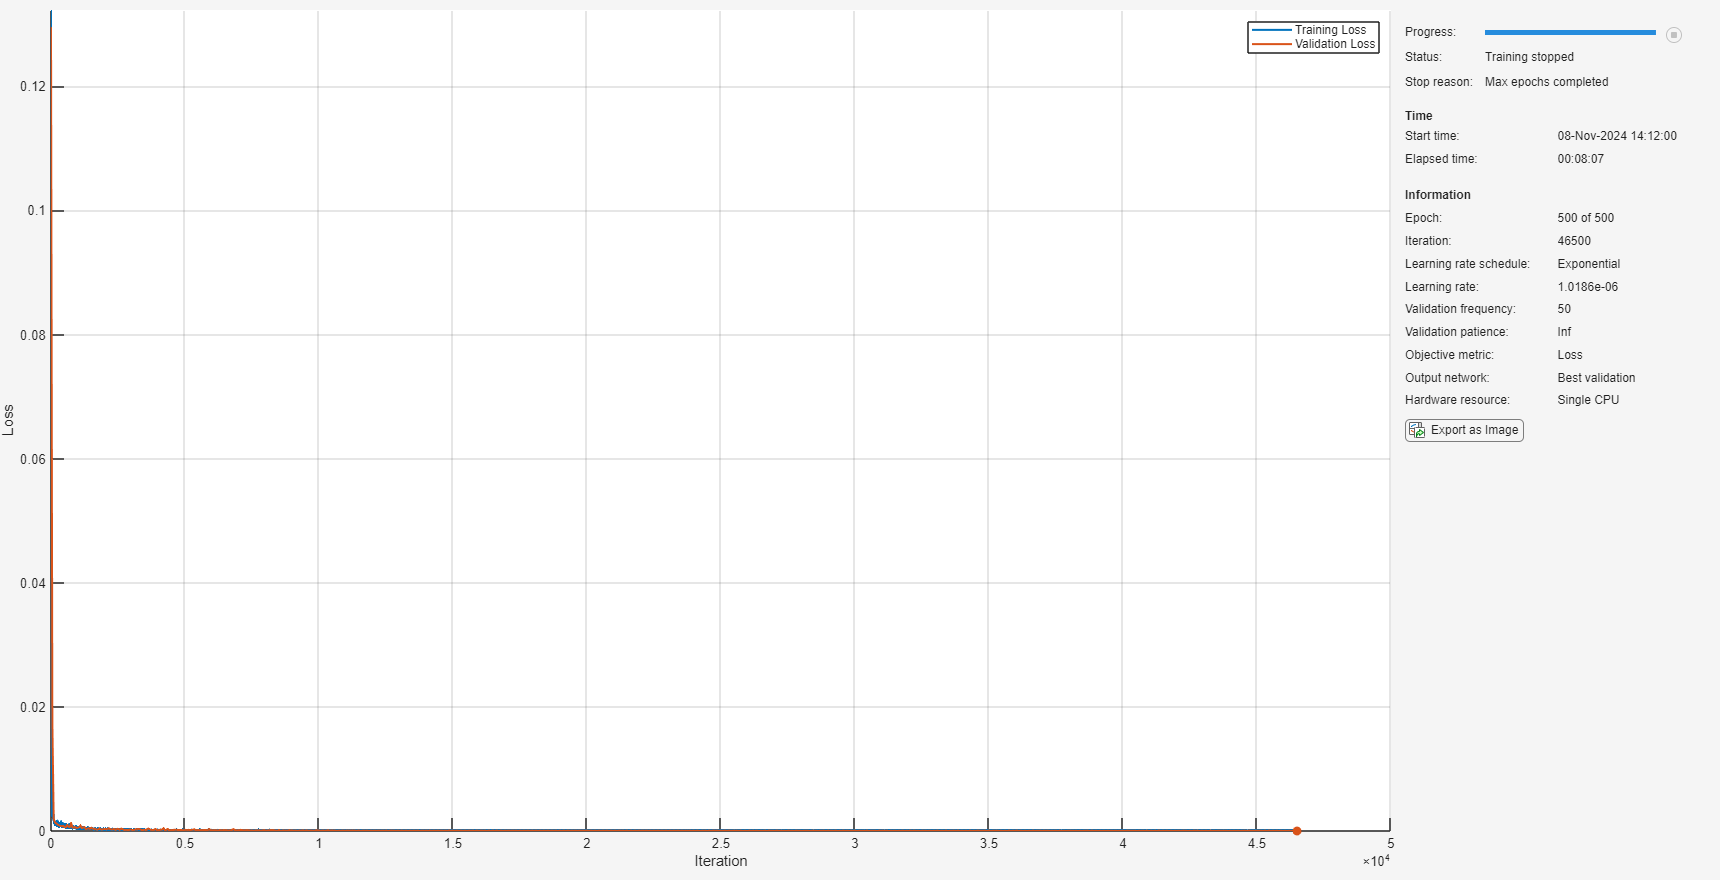

Rnet =   dlnetwork with properties:

         Layers: [10×1 nnet.cnn.layer.Layer]
    Connections: [9×2 table]
     Learnables: [11×3 table]
          State: [6×3 table]
     InputNames: {'sequenceinput'}
    OutputNames: {'layer'}
    Initialized: 1
  View summary with summary.

regularization = 0;
lr_i = 1e-2;
lr_f = 1e-6;
plots = 'training-progress';

Rnet = NNtrain(Rnet, dlXseq_tr, dlYseq_tr, dlXseq_val, dlYseq_val, regularization, lr_i, lr_f, plots)

## Summary

dlYseq_tr_pred = minibatchpredict(Rnet, dlXseq_tr, SequenceLength="shortest");
dlYseq_val_pred = minibatchpredict(Rnet, dlXseq_val, SequenceLength="shortest");

Yseq_tr_pred = extractdata(dlYseq_tr_pred);
Yseq_val_pred = extractdata(dlYseq_val_pred);

trainPerformance = mse(dlYseq_tr_pred, dlYseq_tr);
valPerformance = mse(dlYseq_val_pred, dlYseq_val);

disp(['Rendimiento en el conjunto de entrenamiento: ', num2str(trainPerformance)]);

Rendimiento en el conjunto de entrenamiento: 0.00036306


disp(['Rendimiento en el conjunto de validación: ', num2str(valPerformance)]);

Rendimiento en el conjunto de validación: 0.00034426



analyzeNetwork(Rnet);
summary(Rnet)

   Initialized: true
   Number of learnables: 2.2k
   Inputs:
      1   'sequenceinput'   Sequence input with 27 dimensions


# Performance analysis

## Complete timeseries

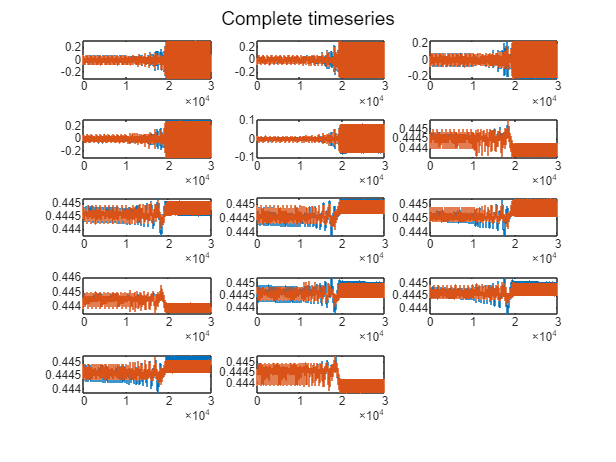

pred = extractdata(minibatchpredict(Rnet, dlXseq, SequenceLength="shortest"));
figure
subplot(ceil(Noutputs/3), 3, 1)
stairs(1:Nseq, cellfun(@(x) x(1), Yseq))
hold on
stairs(1:Nseq, pred(1, :))
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    stairs(1:Nseq, cellfun(@(x) x(idx), Yseq))
    hold on
    stairs(1:Nseq, pred(idx, :))
    hold off
end
sgtitle('Complete timeseries');

## Error histogram

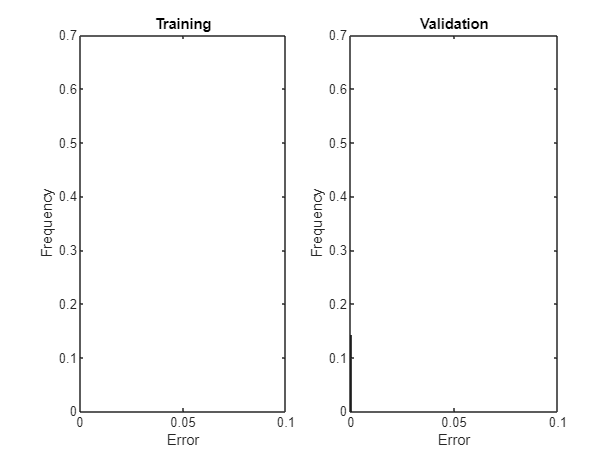

figure
subplot(1, 2, 1)
histogram(mean((Yseq_tr_pred - extractdata(dlYseq_tr)).^2, 2), 10, 'Normalization', 'probability')
title("Training")
xlabel("Error"); xlim([0, 0.1])
ylabel("Frequency")

subplot(1, 2, 2)
histogram(mean((Yseq_val_pred - extractdata(dlYseq_val)).^2, 2), 10, 'Normalization', 'probability')
title("Validation")
xlabel("Error"); xlim([0, 0.1])
ylabel("Frequency")

## Regression

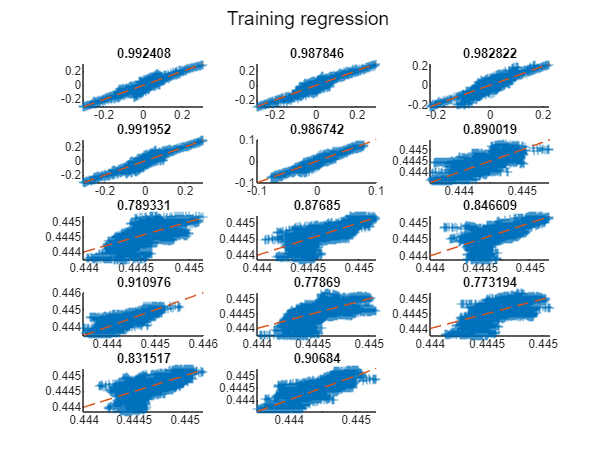

% xlabel("Predicted")
% ylabel("Actual")

figure
title("Training")
subplot(ceil(Noutputs/3), 3, 1)
scatter(Yseq_tr_pred(1, :), extractdata(dlYseq_tr(1, :)), "+")
title(corr(Yseq_tr_pred(1, :)', extractdata(dlYseq_tr(1, :))'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Yseq_tr_pred(idx, :), extractdata(dlYseq_tr(idx, :)), "+")
    title(corr(Yseq_tr_pred(idx, :)', extractdata(dlYseq_tr(idx, :))'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Training regression');

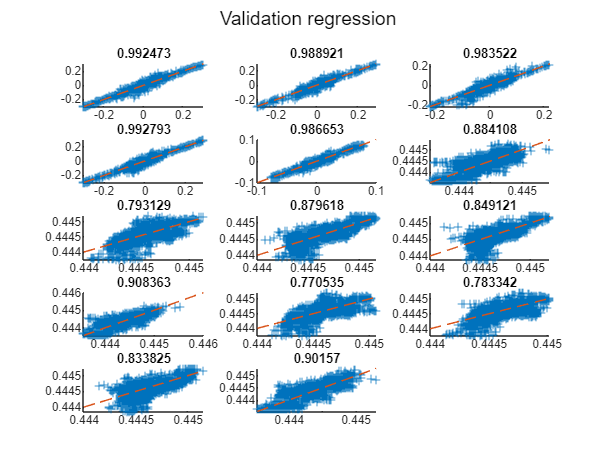


figure
subplot(ceil(Noutputs/3), 3, 1)
scatter(Yseq_val_pred(1, :), extractdata(dlYseq_val(1, :)), "+")
title(corr(Yseq_val_pred(1, :)', extractdata(dlYseq_val(1, :))'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Yseq_val_pred(idx, :), extractdata(dlYseq_val(idx, :)), "+")
    title(corr(Yseq_val_pred(idx, :)', extractdata(dlYseq_val(idx, :))'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Validation regression');

## Weight matrix analysis

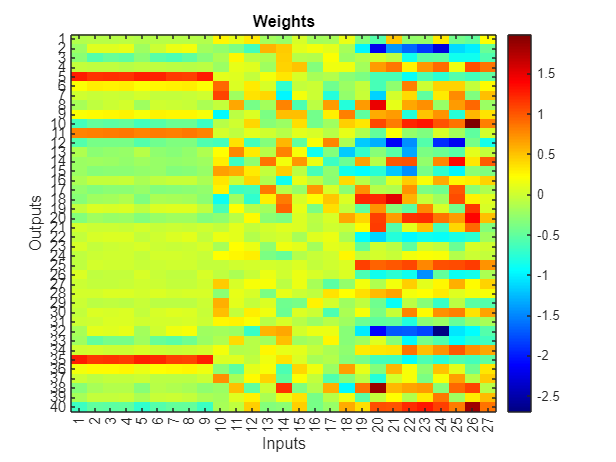

weights_input_hidden = Rnet.Learnables.Value;
weights_input_hidden = extractdata(weights_input_hidden{1});

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Weights');

xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));

Near zero weights

weights_treshold = 0.01 * max(max(abs(weights_input_hidden)))

weights_treshold = single
0.0269

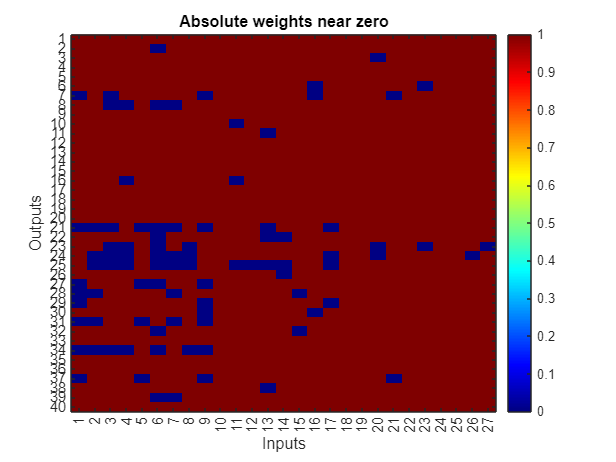

weights_input_hidden(abs(weights_input_hidden) <= weights_treshold) = 0;
weights_input_hidden(abs(weights_input_hidden) > weights_treshold) = 1;

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Absolute weights near zero');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));

# Architecture search

% % Crear carpetas para guardar los resultados
% mkdir('neural_network/results/architectures');
% mkdir('neural_network/results/performance');
% 
% % Definir rango de arquitecturas
% Nlayers_range = 1:10;
% Nneurons_range = 2:2:30;
% 
% % Inicializar matrices para guardar resultados
% results = [];
% 
% % Iterar sobre el rango de arquitecturas
% for Nlayers = Nlayers_range
%     for Nneurons = Nneurons_range
%         try
%             net_name = [num2str(Nlayers) 'L' num2str(Nneurons) 'N'];
% 
%             % Architecture
%             Hactivation = 'tanhLayer';
%             Oactivation = 'tanhLayer';
%             dropout = 0;
%             Winitializer = 'narrow-normal';
%             Binitializer = 'narrow-normal';
%             net = FFNN(Ninputs, Noutputs, Nlayers, Nneurons, Hactivation, Oactivation, dropout, Winitializer, Binitializer).net;
% 
%             % Training
%             regularization = 0*1e-4;
%             lr_i = 1e-2;
%             lr_f = 1e-6;
%             plots = 'none';
%             net = NNtrain(net, X_train, Y_train, X_val, Y_val, regularization, lr_i, lr_f, plots);
% 
%             % Evaluating
%             trainPerformance = mse(net.predict(X_train'), Y_train');
%             valPerformance = mse(net.predict(X_val'), Y_val');
%             diffPerformance = valPerformance - trainPerformance;
% 
%             % Results
%             results = [results; Nlayers, Nneurons, trainPerformance, valPerformance, diffPerformance];
% 
%             % Save net
%             save(fullfile('neural_network/results/architectures', ['A' net_name '.mat']), 'net');            
% 
%         catch ME
%             disp(['Error ' net_name ': ' ME.message]);
%             continue;
%         end
%     end
% end
% csvwrite('neural_network/results/performance/performance.csv', results);

Heatmap

% data = readmatrix('neural_network/results/performance/performance.csv');
% Narchitectures = length(data)
% Nlayers_range = sort(unique(data(:, 1)))'
% Nneurons_range = sort(unique(data(:, 2)))'
% 
% % Performance in percentage
% trainPerformance = reshape(data(:, 3), [length(Nneurons_range), length(Nlayers_range)])*100;
% valPerformance = reshape(data(:, 4), [length(Nneurons_range), length(Nlayers_range)])*100;
% diffPerformance = -reshape(data(:, 5), [length(Nneurons_range), length(Nlayers_range)])*100;
% 
% z_max = 100;
% trainPerformance(trainPerformance > z_max) = z_max;
% valPerformance(valPerformance > z_max) = z_max;
% 
% figure;
% heatmap(Nlayers_range, Nneurons_range, round(trainPerformance, 4));
% xlabel('Layers');
% ylabel('Neurons/Layer');
% title('Train MSE (%)');
% colorbar;
% colormap jet;
% 
% figure;
% heatmap(Nlayers_range, Nneurons_range, round(valPerformance, 4));
% xlabel('Layers');
% ylabel('Neurons/Layer');
% title('Validation MSE (%)');
% colorbar;
% colormap jet;
% 
% figure;
% heatmap(Nlayers_range, Nneurons_range, round(diffPerformance, 4));
% xlabel('Layers');
% ylabel('Neurons/Layer');
% title('(Validation - Train) MSE (%)');
% colorbar;
% colormap jet;

3d Plot

% figure;
% surf(Nlayers_range, Nneurons_range, trainPerformance, 'EdgeColor', 'none');
% xlabel('Layers');
% ylabel('Neurons/Layer');
% yticks(Nneurons_range)
% zlabel('Performance %');
% title('Train MSE');
% colorbar;
% colormap jet;
% shading interp;
% 
% figure;
% surf(Nlayers_range, Nneurons_range, valPerformance, 'EdgeColor', 'none');
% xlabel('Layers');
% ylabel('Neurons/Layer');
% yticks(Nneurons_range)
% zlabel('Performance %');
% title('Validation MSE');
% colorbar;
% colormap jet;
% shading interp;
% 
% figure;
% surf(Nlayers_range, Nneurons_range, trainPerformance, 'EdgeColor', 'none');
% hold on
% surf(Nlayers_range, Nneurons_range, valPerformance, 'EdgeColor', 'none');
% hold off
% 
% xlabel('Layers');
% ylabel('Neurons/Layer');
% yticks(Nneurons_range)
% zlabel('Performance %');
% legend(["Train", "Validation"])
% colorbar;
% colormap jet;
% shading interp;
% 
% figure;
% surf(Nlayers_range, Nneurons_range, diffPerformance, 'EdgeColor', 'none');
% xlabel('Layers');
% ylabel('Neurons/Layer');
% yticks(Nneurons_range)
% zlabel('Performance diference %');
% legend("Validation-Train")
% colorbar;
% colormap jet;
% shading interp;

Tables

% Nbest_architectures = 4;
% 
% valid_idx = (trainPerformance < z_max) & (valPerformance < z_max);
% [valid_rows, valid_cols] = find(valid_idx);
% 
% results_table = [];
% for i = 1:length(valid_rows)
%     row = valid_rows(i);
%     col = valid_cols(i);
% 
%     mse_train = trainPerformance(row, col);
%     mse_val = valPerformance(row, col);
%     mse_diff = abs(diffPerformance(row, col));
% 
%     results_table = [results_table; col, row*2, mse_train, mse_val, mse_diff];
% end
% 
% train_table = sortrows(results_table, 3);
% validation_table = sortrows(results_table, 4);
% diff_table = sortrows(results_table, 5);
% 
% train_table = train_table(1:Nbest_architectures, :);
% validation_table = validation_table(1:Nbest_architectures, :);
% diff_table = diff_table(1:Nbest_architectures, :);
% 
% train_table = array2table(train_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Diff'});
% validation_table = array2table(validation_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr',  'MSE_val', 'Diff'});
% diff_table = array2table(diff_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Diff'});
% 
% disp('Tabla de mejores rendimientos en entrenamiento:');
% disp(train_table);
% 
% disp('Tabla de mejores rendimientos en validación:');
% disp(validation_table);
% 
% disp('Tabla de mejores diferencias entre entrenamiento y validación:');
% disp(diff_table);

% load('neural_network/results/architectures/A1L2N.mat', 'net');
% net
% summary(net)
% 
% trainPerformance = mse(net.predict(X_train'), Y_train')*100
% valPerformance = mse(net.predict(X_val'), Y_val')*100
% diffPerformance = (valPerformance - trainPerformance)

% i = 1;
% for Nlayers = Nlayers_range
%     for Nneurons = Nneurons_range
%         load(['neural_network/results/architectures/A' num2str(Nlayers) 'L' num2str(Nneurons) 'N.mat'], 'net');
%         trainPerformance = mse(net.predict(X_train'), Y_train');
%         valPerformance = mse(net.predict(X_val'), Y_val');
%         diffPerformance = (valPerformance - trainPerformance);
%         data(i, 3) = trainPerformance;
%         data(i, 4) = valPerformance;
%         data(i, 5) = diffPerformance;
%         i = i + 1;
%     end
% end
% 
% % Performance in percentage
% trainPerformance = reshape(data(:, 3), [length(Nneurons_range), length(Nlayers_range)])*100;
% valPerformance = reshape(data(:, 4), [length(Nneurons_range), length(Nlayers_range)])*100;
% diffPerformance = -reshape(data(:, 5), [length(Nneurons_range), length(Nlayers_range)])*100;
% 
% z_max = 100;
% trainPerformance(trainPerformance > z_max) = z_max;
% valPerformance(valPerformance > z_max) = z_max;
% 
% figure;
% heatmap(Nlayers_range, Nneurons_range, round(trainPerformance, 4));
% xlabel('Layers');
% ylabel('Neurons/Layer');
% title('Train MSE (%)');
% colorbar;
% colormap jet;
% 
% figure;
% heatmap(Nlayers_range, Nneurons_range, round(valPerformance, 4));
% xlabel('Layers');
% ylabel('Neurons/Layer');
% title('Validation MSE (%)');
% colorbar;
% colormap jet;
% 
% figure;
% heatmap(Nlayers_range, Nneurons_range, round(diffPerformance, 4));
% xlabel('Layers');
% ylabel('Neurons/Layer');
% title('(Validation - Train) MSE (%)');
% colorbar;
% colormap jet;

Tables

% Nbest_architectures = 4;
% 
% valid_idx = (trainPerformance < z_max) & (valPerformance < z_max);
% [valid_rows, valid_cols] = find(valid_idx);
% 
% results_table = [];
% for i = 1:length(valid_rows)
%     row = valid_rows(i);
%     col = valid_cols(i);
% 
%     mse_train = trainPerformance(row, col);
%     mse_val = valPerformance(row, col);
%     mse_diff = abs(diffPerformance(row, col));
% 
%     results_table = [results_table; col, row*2, mse_train, mse_val, mse_diff];
% end
% 
% train_table = sortrows(results_table, 3);
% validation_table = sortrows(results_table, 4);
% diff_table = sortrows(results_table, 5);
% 
% train_table = train_table(1:Nbest_architectures, :);
% validation_table = validation_table(1:Nbest_architectures, :);
% diff_table = diff_table(1:Nbest_architectures, :);
% 
% train_table = array2table(train_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Diff'});
% validation_table = array2table(validation_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr',  'MSE_val', 'Diff'});
% diff_table = array2table(diff_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Diff'});
% 
% disp('Tabla de mejores rendimientos en entrenamiento:');
% disp(train_table);
% 
% disp('Tabla de mejores rendimientos en validación:');
% disp(validation_table);
% 
% disp('Tabla de mejores diferencias entre entrenamiento y validación:');
% disp(diff_table);